[p1 p2 p3 p4 p5 p6 Kr Kw]=generaparametros_avion([2 5 0 9 8 5 3 9])

p1 = 0.3225

p2 = 58.0625

p3 = 0.2838

p4 = 0.0161

p5 = 0.4225

p6 = 0.0223

Kr = 1.2094

Kw = 1.4188

Gs=tf([p2*p6 p1*p2*p6-p2*p3*p4], [1 p1+p5 p2*p4+p1*p5 0])

Gs =
 
       1.292 s + 0.151
  -------------------------
  s^3 + 0.745 s^2 + 1.073 s
 
Continuous-time transfer function.



zpk(Gs)

ans =
 
     1.2919 (s+0.1169)
  ------------------------
  s (s^2 + 0.745s + 1.073)
 
Continuous-time zero/pole/gain model.



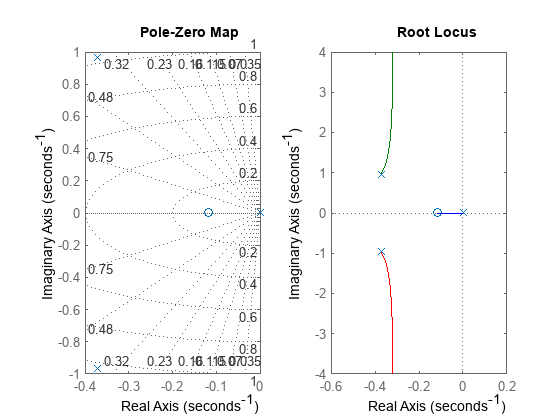

close all
figure
subplot(121);
pzmap(Gs); 
sgrid;
subplot(122);
rlocus(Gs); 

T=0.1;
Gz=c2d(Gs, T, 'zoh');
zpk(Gz)

ans =
 
  0.0063211 (z-0.9884) (z+0.9793)
  -------------------------------
   (z-1) (z^2 - 1.918z + 0.9282)
 
Sample time: 0.1 seconds
Discrete-time zero/pole/gain model.



[z, p, K]=zpkdata(Gs,'v');
exp(z*T)

ans = 0.9884

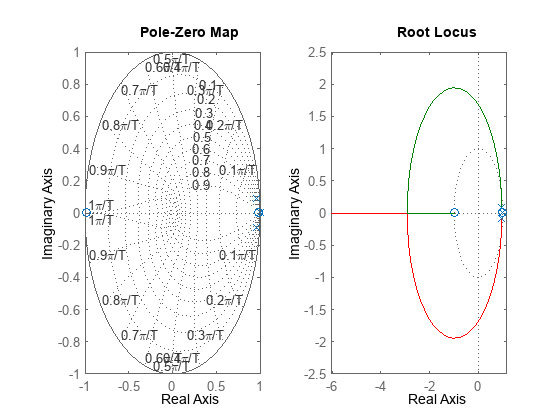

Unrecognized function or variable 'a'.

figure
subplot(121);
pzmap(Gz); 
zgrid;
subplot(122);
rlocus(Gz); a

A=[0 0 p2;0 -p1 p2; 0 -p4 -p5];
B=[0; p3; p6];
C=[1 0 0];
D=[0];
sys=ss(A, B, C, D)

sys =
 
  A = 
             x1        x2        x3
   x1         0         0     58.06
   x2         0   -0.3225     58.06
   x3         0  -0.01613   -0.4225
 
  B = 
            u1
   x1        0
   x2   0.2838
   x3  0.02225
 
  C = 
       x1  x2  x3
   y1   1   0   0
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.



zpk(sys)

ans =
 
     1.2919 (s+0.1169)
  ------------------------
  s (s^2 + 0.745s + 1.073)
 
Continuous-time zero/pole/gain model.




MC=ctrb(sys) % matriz de controlabilidad

MC =          0    1.2919   -0.8115
    0.2838    1.2004   -1.1986
    0.0222   -0.0140   -0.0135


[B A*B A^2*B] % comprobamos el cálculo manualmente

ans =          0    1.2919   -0.8115
    0.2838    1.2004   -1.1986
    0.0222   -0.0140   -0.0135


rank(MC)

ans = 3

MO=obsv(sys)

MO =     1.0000         0         0
         0         0   58.0625
         0   -0.9363  -24.5314


[C;C*A;C*A*A] % comprobamos el cálculo manualmente

ans =     1.0000         0         0
         0         0   58.0625
         0   -0.9363  -24.5314


rank(MO)

ans = 3

canon(sys) % forma canónica del sistema

ans =
 
  A = 
            x1       x2       x3
   x1        0        0        0
   x2        0  -0.3725   0.9663
   x3        0  -0.9663  -0.3725
 
  B = 
            u1
   x1  0.07038
   x2   0.7878
   x3    1.225
 
  C = 
            x1       x2       x3
   y1        2   0.6884  -0.5575
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.



eig(A) % obtenemos los autovalroes de A

ans =    0.0000 + 0.0000i
  -0.3725 + 0.9663i
  -0.3725 - 0.9663i


[z p k]=zpkdata(Gs,'v'); % los polos coinciden
p

p =    0.0000 + 0.0000i
  -0.3725 + 0.9663i
  -0.3725 - 0.9663i


sysz=c2d(sys, T, 'zoh')

sysz =
 
  A = 
              x1         x2         x3
   x1          1  -0.004563      5.677
   x2          0     0.9638      5.585
   x3          0  -0.001551     0.9541
 
  B = 
             u1
   x1  0.006321
   x2   0.03418
   x3  0.002153
 
  C = 
       x1  x2  x3
   y1   1   0   0
 
  D = 
       u1
   y1   0
 
Sample time: 0.1 seconds
Discrete-time state-space model.



[z p k]=zpkdata(sysz,'v')

z =     0.9884
   -0.9793


p =    1.0000 + 0.0000i
   0.9589 + 0.0930i
   0.9589 - 0.0930i


k = 0.0063

[z p k]=zpkdata(Gz,'v')

z =     0.9884
   -0.9793


p =    1.0000 + 0.0000i
   0.9589 + 0.0930i
   0.9589 - 0.0930i


k = 0.0063

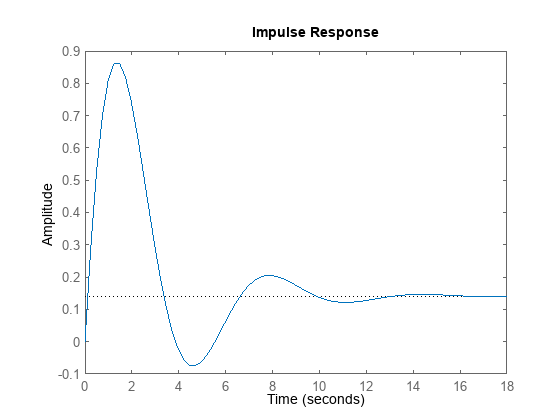

figure
impulse(Gs)

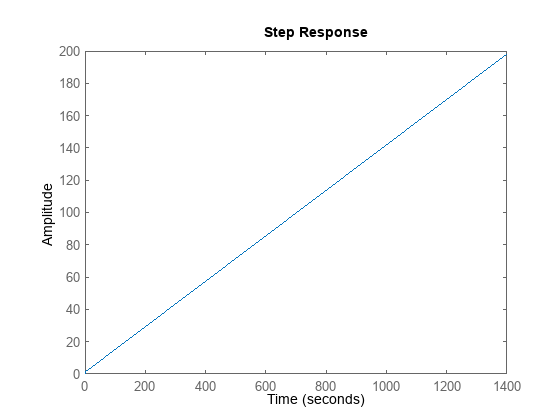

figure
step(sys)